clear ;
close all;


load ryan2_gen_data_new.mat

idx1 = find(contains([battery_dataset_new.key],'b1','IgnoreCase',true))

idx1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36


idx2 = find(contains([battery_dataset_new.key],'b2','IgnoreCase',true))

idx2 =     37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79


idx3 = find(contains([battery_dataset_new.key],'b3','IgnoreCase',true))

idx3 =     80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119


idx12 = [idx1 idx2]

idx12 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx13 = [idx1 idx3]

idx13 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    80    81    82    83    84    85    86    87    88    89    90    91    92    93


idx23 = [idx2 idx3]

idx23 =     37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86


idxAll = (1:length(battery_dataset_new))

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx123 = [idx1 idx2 idx3]

idx123 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


전체 데이타 셋의 discahrge Q 를 smooth해서 표시

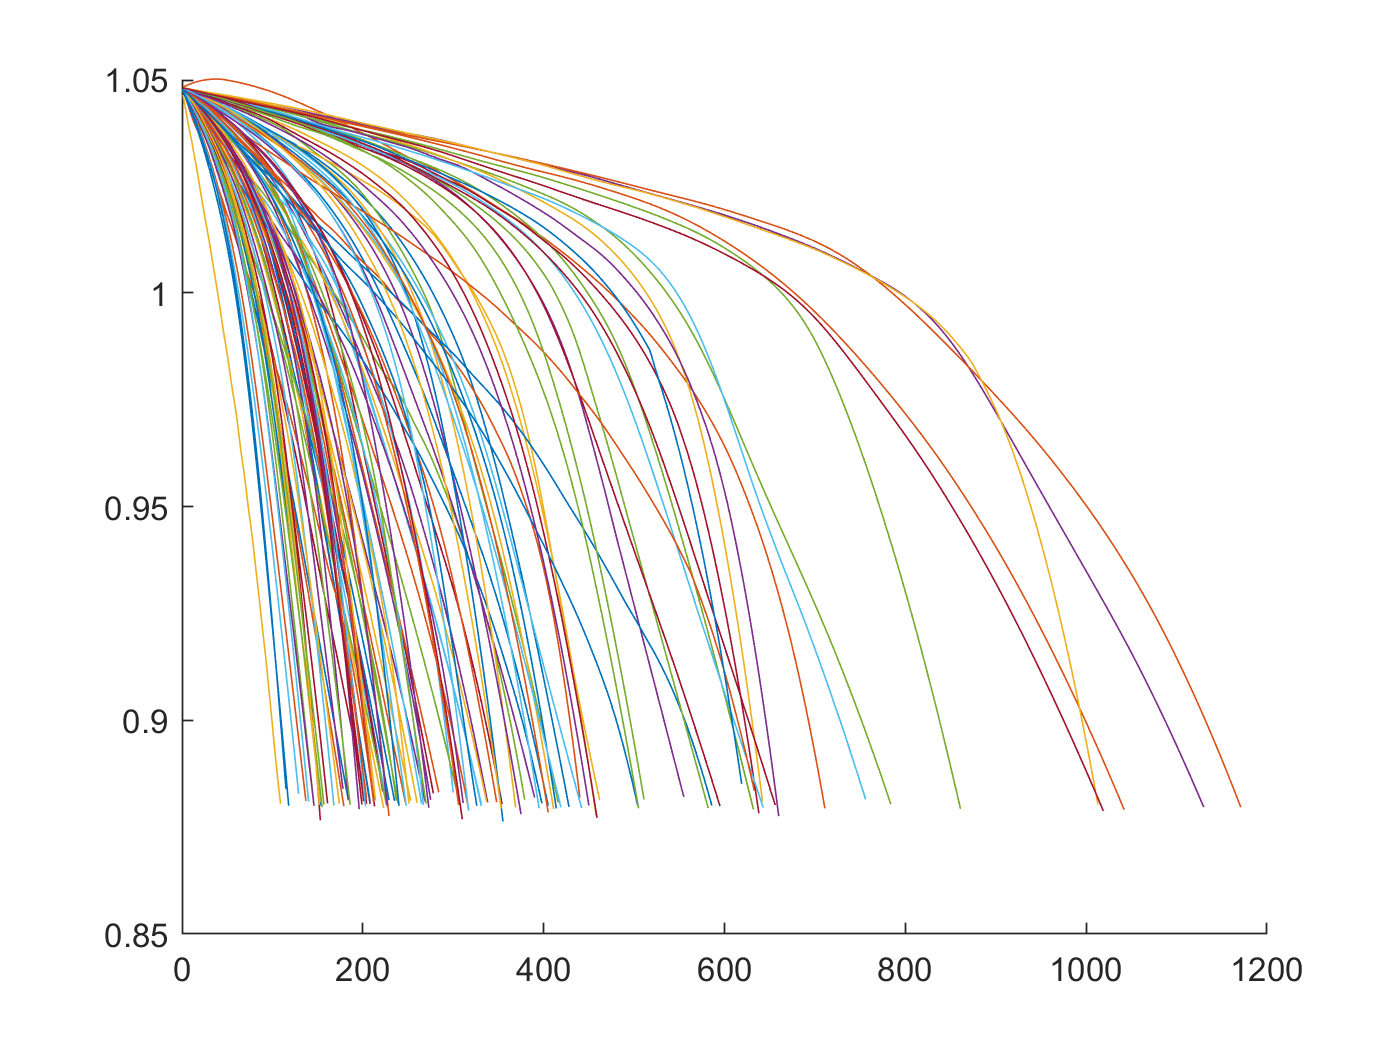

% here
figure
hold on
for i=1:length(idxAll)
    plot(battery_dataset_new(idxAll(i)).QDischargeSmooth)
end
hold off

batch 1,2 의 discharge Q 만 표시 = training set으로 사용할 예정

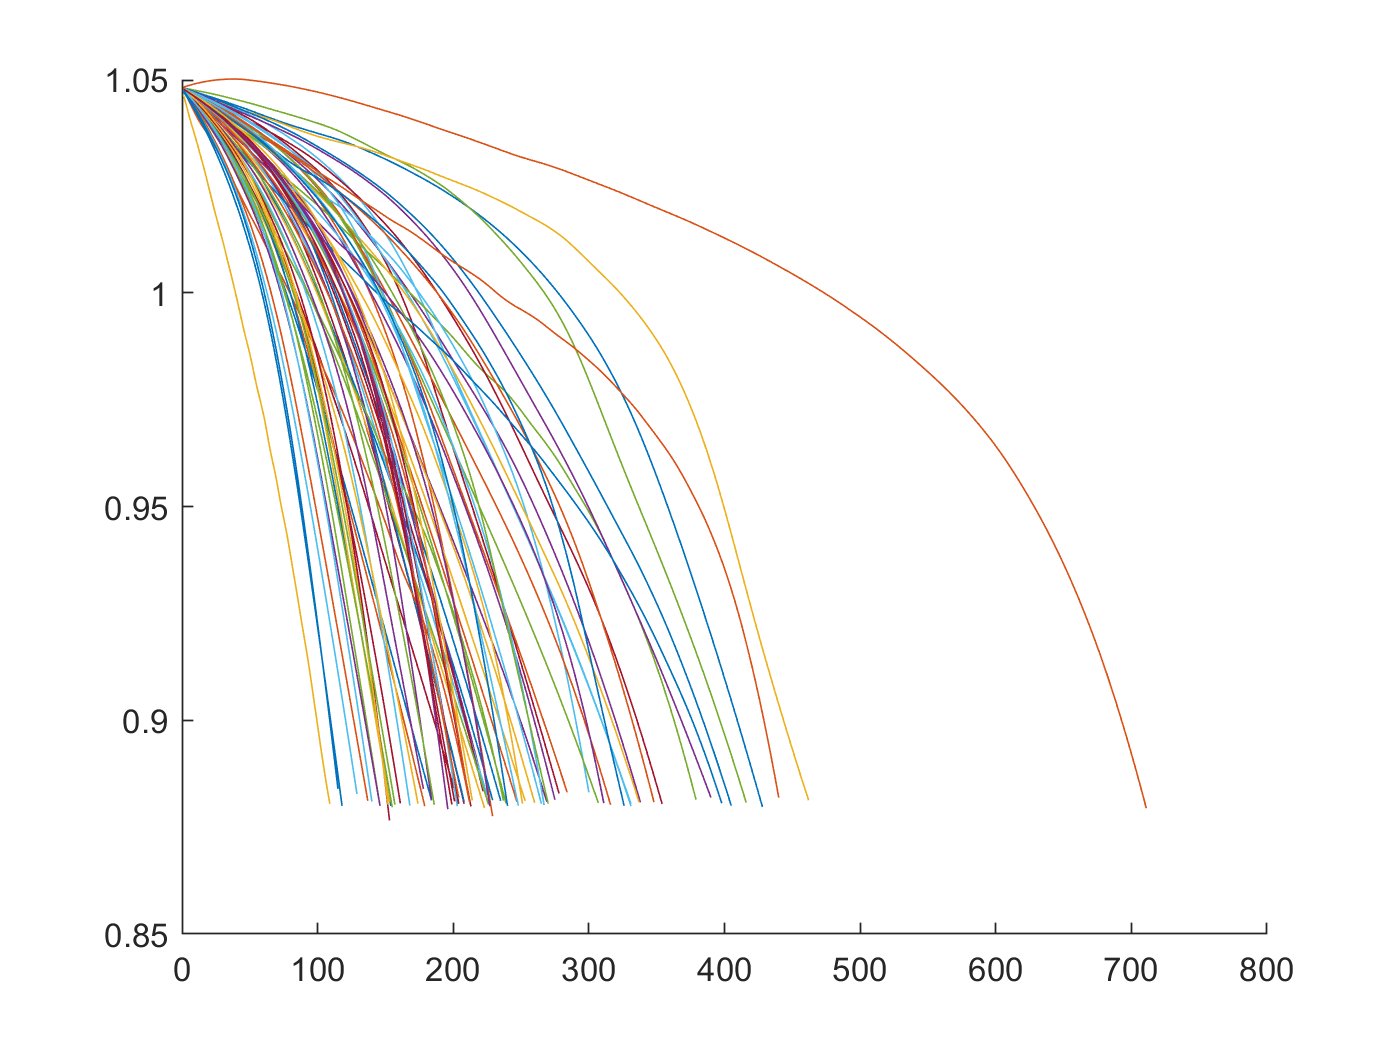

figure
hold on
for i=1:length(idx12)
    plot(battery_dataset_new(idx12(i)).QDischargeSmooth)
end
hold off

batch 3 의 discharge Q 만 표시 = test set으로 사용할 예정

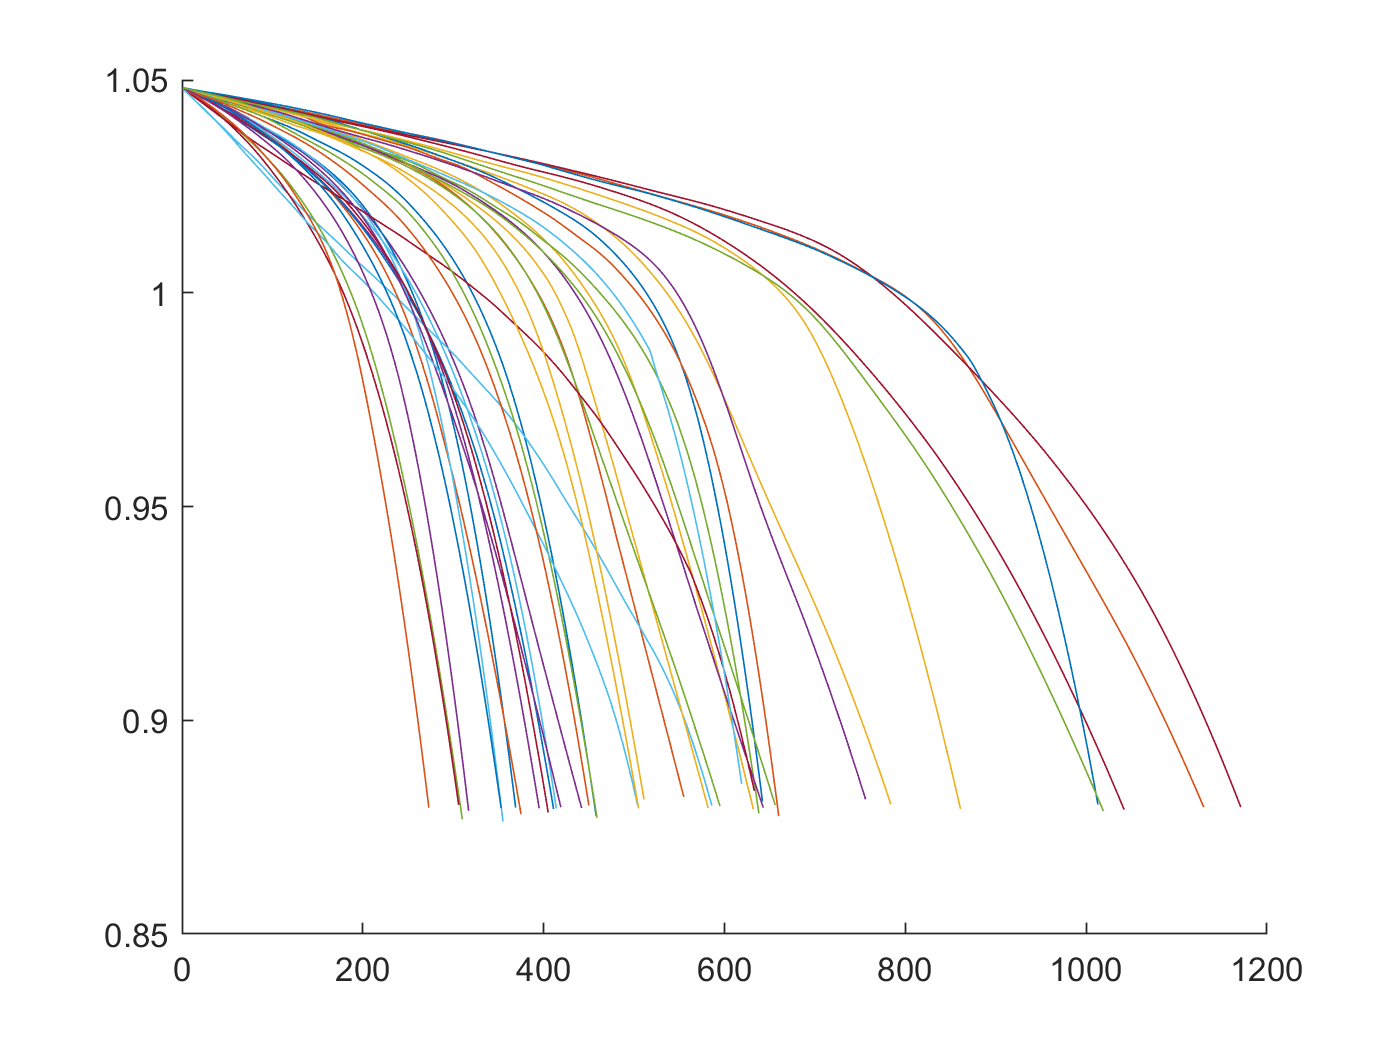

figure
hold on
for i=1:length(idx3)
    plot(battery_dataset_new(idx3(i)).QDischargeSmooth)
end
hold off

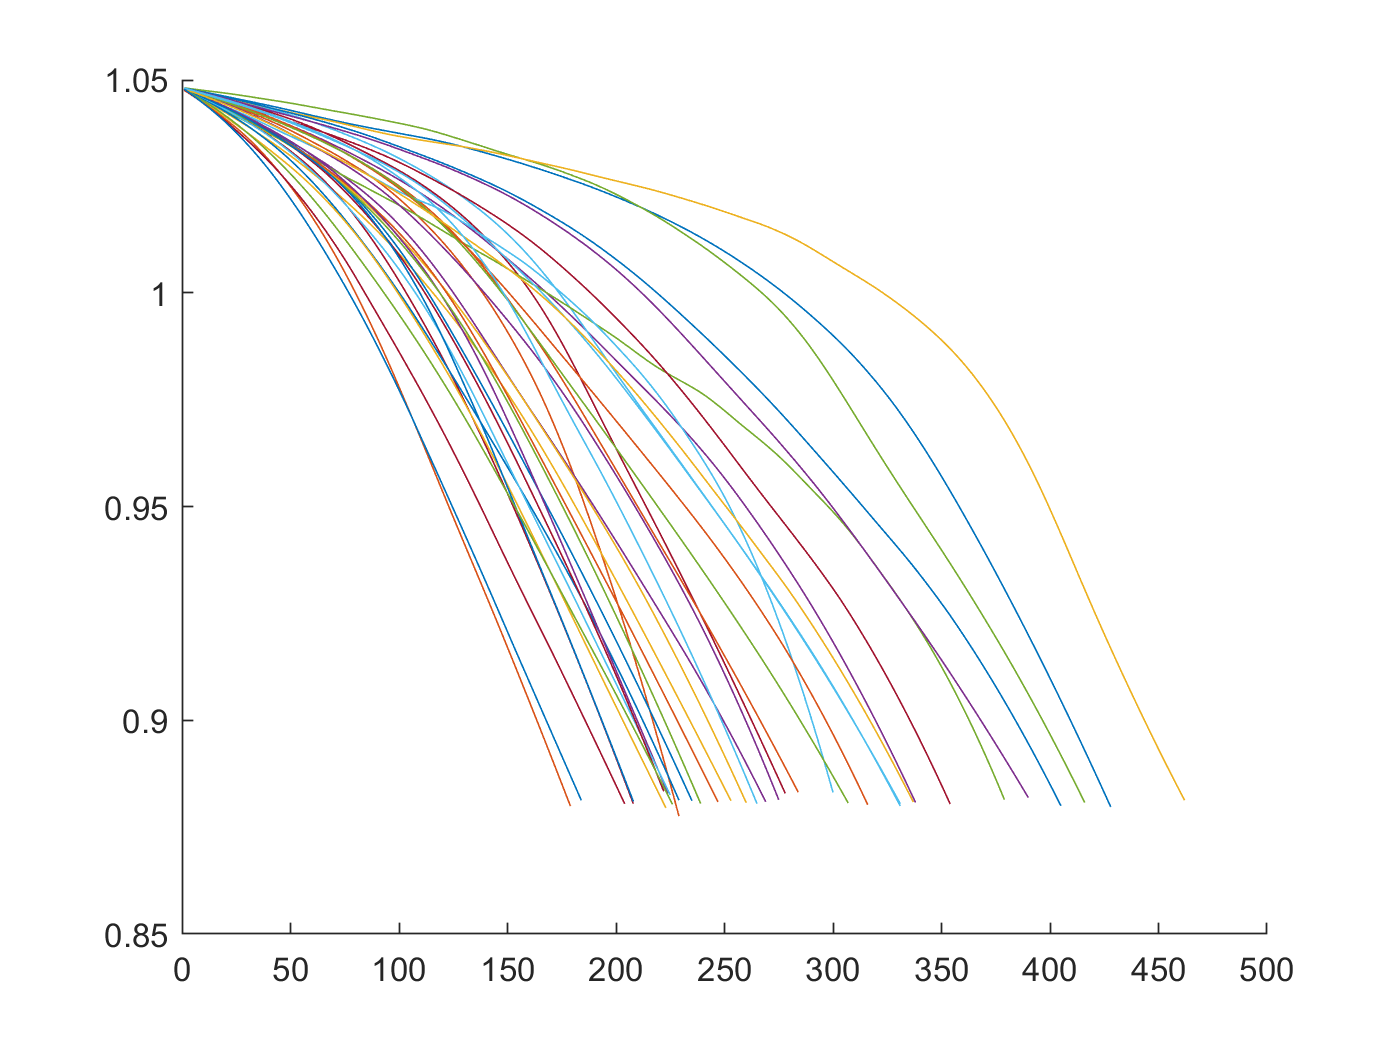


figure
hold on
for i=1:length(idx1)
    plot(battery_dataset_new(idx1(i)).QDischargeSmooth)
end
hold off

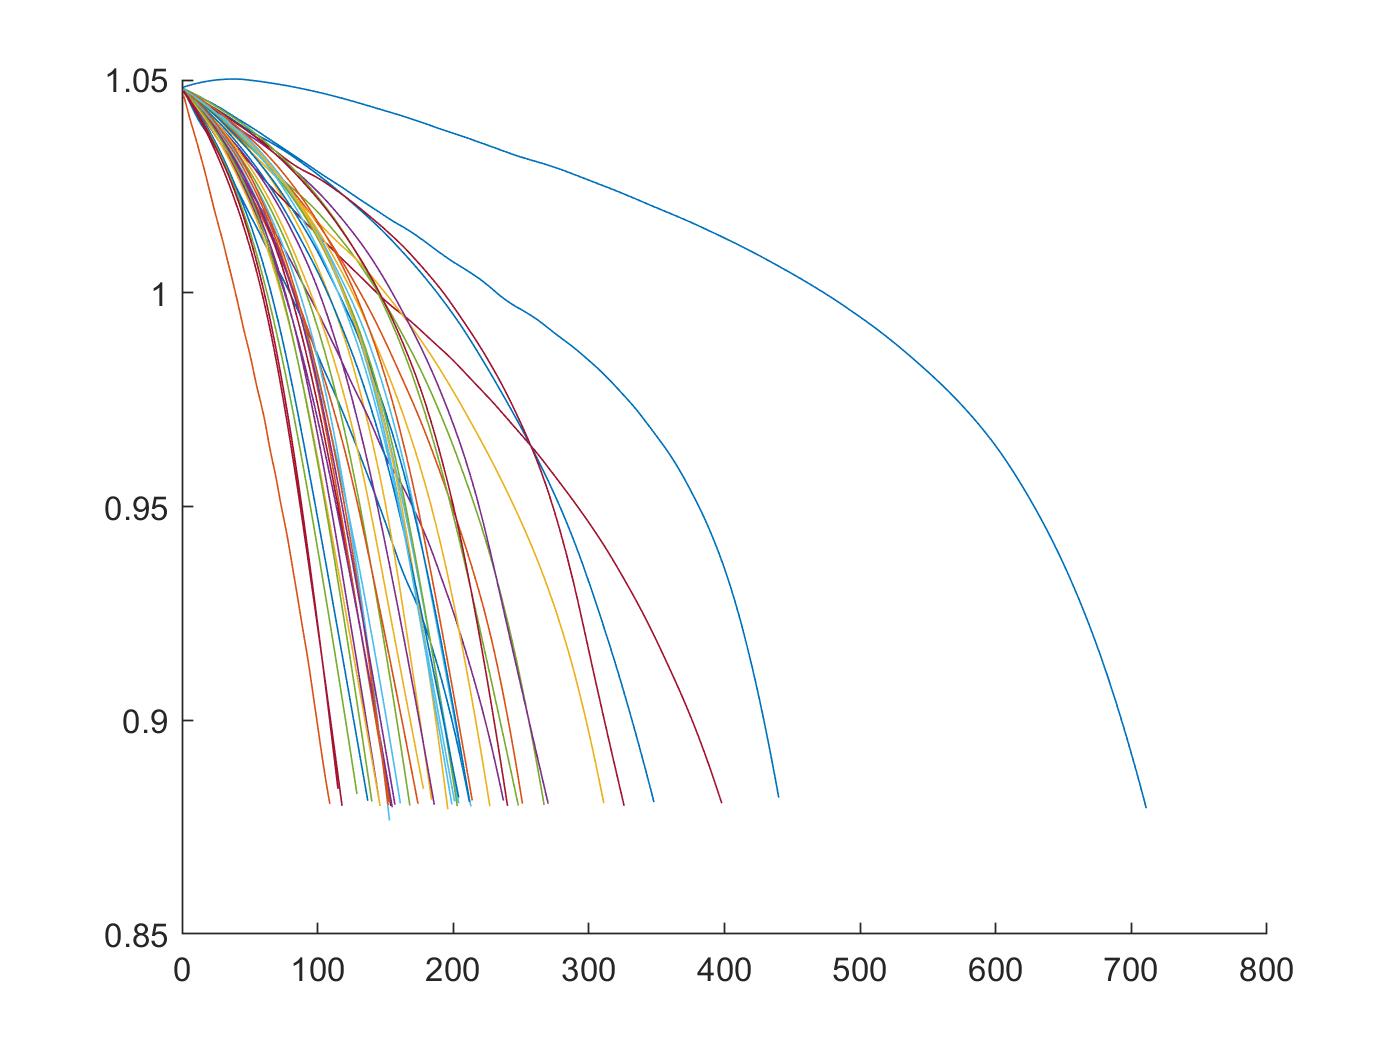


figure
hold on
for i=1:length(idx2)
    plot(battery_dataset_new(idx2(i)).QDischargeSmooth)
end
hold off


figure
hold on
for i=1:length(idx3)
    plot(battery_dataset_new(idx3(i)).QDischargeSmooth)
end
hold off

test dataset (batch1,2) 에서 값을 정규화하기

%idx = idxAll; %RMSE = 1032  - 잘 동작
idx = idx12 ; % training set - 잘 동작하지 않음
%idx = idx13 ; % training set - 잘 동작하지 않음
%idx = idx1;
key = [battery_dataset_new(idx).key]';
s = string([battery_dataset_new(idx).policy])

s = "4_4C-80PER_4_4C4_8C-80PER_4_8C4_8C-80PER_4_8C5_4C-40PER_3_6C5_4C-50PER_3C5_4C-60PER_3C5_4C-60PER_3C5_4C-60PER_3_6C5_4C-60PER_3_6C5_4C-70PER_3C5_4C-70PER_3C5_4C-80PER_5_4C5_4C-80PER_5_4C6C-30PER_3_6C6C-40PER_3C6C-40PER_3C6C-40PER_3_6C6C-40PER_3_6C6C-50PER_3C6C-50PER_3C6C-50PER_3_6C6C-50PER_3_6C6C-60PER_3C6C-60PER_3C7C-30PER_3_6C7C-30PER_3_6C7C-40PER_3C7C-40PER_3C7C-40PER_3_6C7C-40PER_3_6C8C-15PER_3_6C8C-15PER_3_6C8C-25PER_3_6C8C-25PER_3_6C8C-35PER_3_6C8C-35PER_3_6C1C_4PER_6C2C_10PER_6C2C_2PER_5C2C_7PER_5_5C3_6C_22PER_5_5C3_6C_2PER_4_85C3_6C_30PER_6C3_6C_9PER_5C4C_13PER_5C4C_31PER_54C_40PER_6C4C_4PER_4_85C4_4C_24PER_5C4_4C_47PER_5_5C4_4C_55PER_6C4_4C_8PER_4_85C4_65C_19PER_4_85C4_65C_44PER_5C4_65C_69PER_6C4_8C_80PER_4_8C4_8C_80PER_4_8C4_8C_80PER_4_8C4_9C_27PER_4_75C4_9C_61PER_4_5C4_9C_69PER_4_25C5_2C_10PER_4_75C5_2C_37PER_4_5C5_2C_50PER_4_25C5_2C_58PER_4C5_2C_66PER_3_5C5_2C_71PER_3C5_6C_25PER_4_5C5_6C_38PER_4_25C5_6C_47PER_4C5_6C_58PER_3_5C5_6C_5PER_4_75C5_6C_65PER_3C6C_20PER_4_5C6C_

s1 = string([{battery_dataset_new(idx).policy}])

s1 = 1×79 string array
    "4_4C-80PER_4_4C"    "4_8C-80PER_4_8C"    "4_8C-80PER_4_8C"    "5_4C-40PER_3_6C"    "5_4C-50PER_3C"    "5_4C-60PER_3C"    "5_4C-60PER_3C"    "5_4C-60PER_3_6C"    "5_4C-60PER_3_6C"    "5_4C-70PER_3C"    "5_4C-70PER_3C"    "5_4C-80PER_5_4C"    "5_4C-80PER_5_4C"    "6C-30PER_3_6C"    "6C-40PER_3C"    "6C-40PER_3C"    "6C-40PER_3_6C"    "6C-40PER_3_6C"    "6C-50PER_3C"    "6C-50PER_3C"    "6C-50PER_3_6C"    "6C-50PER_3_6C"    "6C-60PER_3C"    "6C-60PER_3C"    "7C-30PER_3_6C"    "7C-30PER_3_6C"    "7C-40PER_3C"    "7C-40PER_3C"    "7C-40PER_3_6C"    "7C-40PER_3_6C"    "8C-15PER_3_6C"    "8C-15PER_3_6C"    "8C-25PER_3_6C"    "8C-25PER_3_6C"    "8C-35PER_3_6C"    "8C-35PER_3_6C"    "1C_4PER_6C"    "2C_10PER_6C"    "2C_2PER_5C"    "2C_7PER_5_5C"    "3_6C_22PER_5_5C"    "3_6C_2PER_4_85C"    "3_6C_30PER_6C"    "3_6C_9PER_5C"    "4C_13PER_5C"    "4C_31PER_5"    "4C_40PER_6C"    "4C_4PER_4_85C"    "4_4C_24PER_5C"    "4_4C_47PER_5_5C"    "4_4C_55PER_6C"    "4_4C_8PER_4_85

policy = [{battery_dataset_new(idx).policy}]';
policy_str = string([{battery_dataset_new(idx).policy}]');
policy_readable = [{battery_dataset_new(idx).policy_readable}]';
policy_readable_str = string([{battery_dataset_new(idx).policy_readable}]');
Ic1 = [{battery_dataset_new(idx).Ic}]';
Ic2 = [battery_dataset_new(idx).Ic];
Ic3 = reshape(Ic2,100,length(policy));
Ic = Ic3';
cycle = [battery_dataset_new(idx).cycle_life ]';
x=Ic;
y=cycle;
[ynorm,ymin,yrate,xnorm,xmin,xrate] = minmax_norm_new(y,x);

min(y)

ans = 109

max(y)

ans = 711


yrate =  max(y) - min(y)

yrate = 602

ymin = min(y)

ymin = 109

ynorm = (y - ymin) / yrate

ynorm =     0.5299
    0.1993
    0.2392
    0.3804
    0.5100
    0.3688
    0.2807
    0.2093
    0.2907
    0.5864


yback = ynorm * yrate + ymin

yback =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


y

y =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


x

x =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001
         0    4.8000    4.7997    4.8001    4.8000    4.8002    4.8001    4.8003    4.8002    4.8001    4.8000    4.8000    4.8002    4.7994    4.7998    4.8000    4.7996    4.8001    4.8001    4.8000    4.8001    4.8000    4.8001    4.7998    4.7997    4.7997    4.7998    4.7997    4.8000    4.7998    4.7999    4.8002    4.7999    4.8000    4.8001    4.8000    4.8000    4.8000    4.8000    4.8001    4.8002    4.7999    4.8000    4.7999    4.8001    4.8001    4.8000    4.7998    4.7999    4

min(min(x))

ans = 0

max(max(x))

ans = 8.0067

xrate =  max(max(x)) - min(min(x))

xrate = 8.0067

xmin = min(min(x))

xmin = 0

xnorm = (x - xmin) / xrate

xnorm =          0    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5496    0.5496    0.5495    0.5496    0.5495    0.5495    0.5496    0.5496    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495
         0    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5994    0.5995    0.5995    0.5994    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995 

xback = xnorm * xrate + xmin

xback =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001
         0    4.8000    4.7997    4.8001    4.8000    4.8002    4.8001    4.8003    4.8002    4.8001    4.8000    4.8000    4.8002    4.7994    4.7998    4.8000    4.7996    4.8001    4.8001    4.8000    4.8001    4.8000    4.8001    4.7998    4.7997    4.7997    4.7998    4.7997    4.8000    4.7998    4.7999    4.8002    4.7999    4.8000    4.8001    4.8000    4.8000    4.8000    4.8000    4.8001    4.8002    4.7999    4.8000    4.7999    4.8001    4.8001    4.8000    4.7998    4.7999 

x

x =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001
         0    4.8000    4.7997    4.8001    4.8000    4.8002    4.8001    4.8003    4.8002    4.8001    4.8000    4.8000    4.8002    4.7994    4.7998    4.8000    4.7996    4.8001    4.8001    4.8000    4.8001    4.8000    4.8001    4.7998    4.7997    4.7997    4.7998    4.7997    4.8000    4.7998    4.7999    4.8002    4.7999    4.8000    4.8001    4.8000    4.8000    4.8000    4.8000    4.8001    4.8002    4.7999    4.8000    4.7999    4.8001    4.8001    4.8000    4.7998    4.7999    4

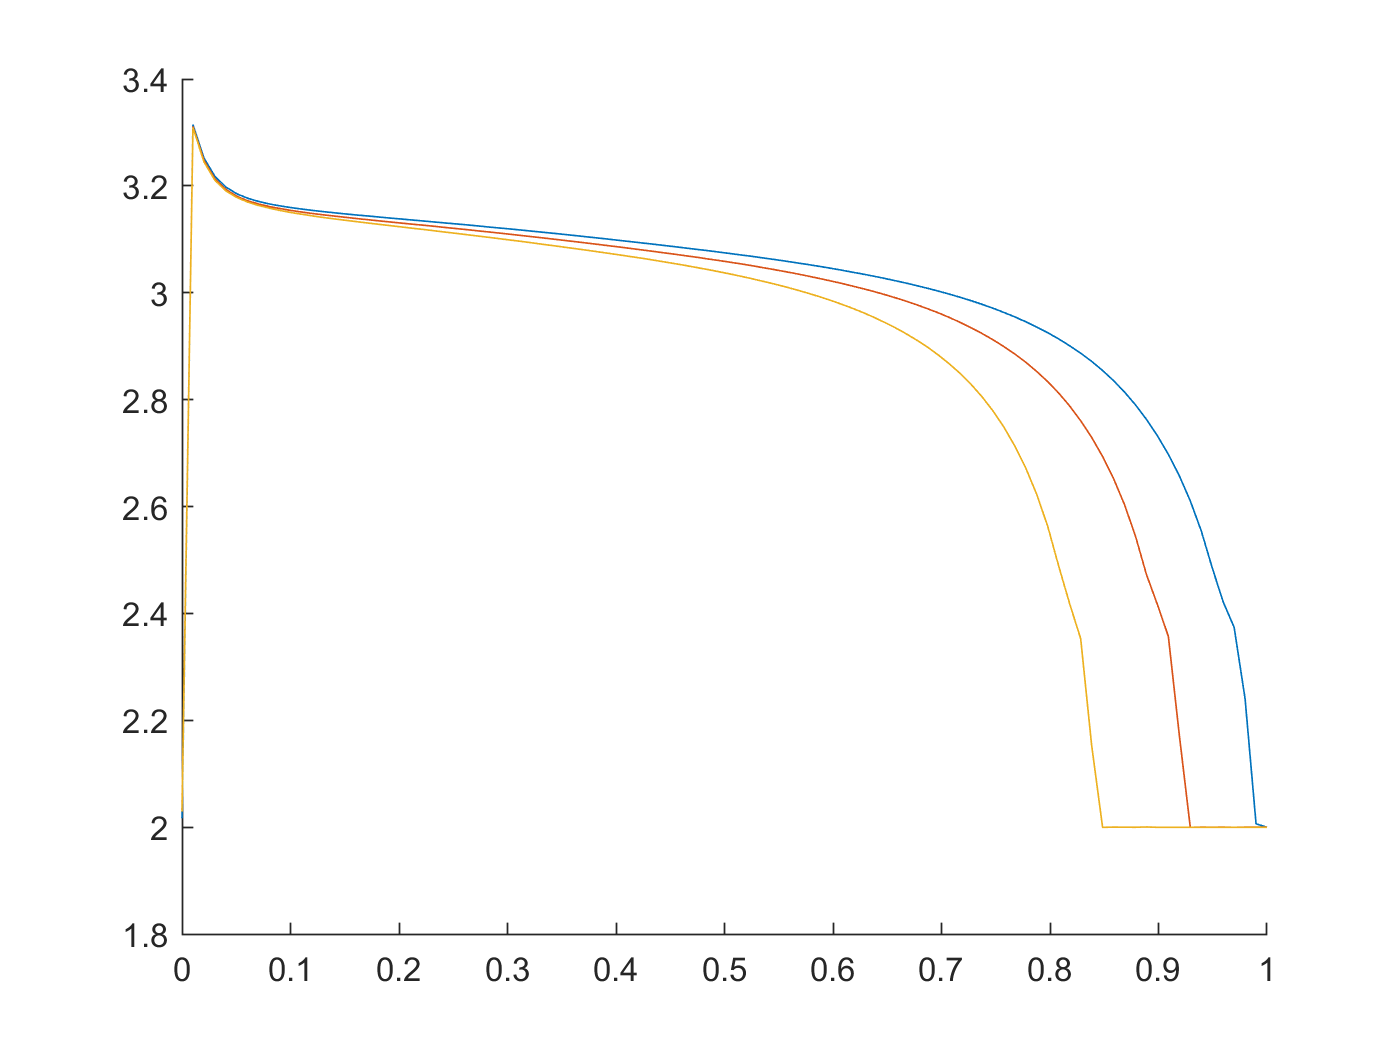

cap_range = linspace(0,1.0,100);
% 이것을 사용하면 안된다.
cap_range12 = linspace(0,1.2,100);


figure
hold on
for i=1:battery_dataset_new(6).cycle_life
    if rem(i,100) == 0
    plot(cap_range,battery_dataset_new(6).Vd(i,:))
    end
end
hold off

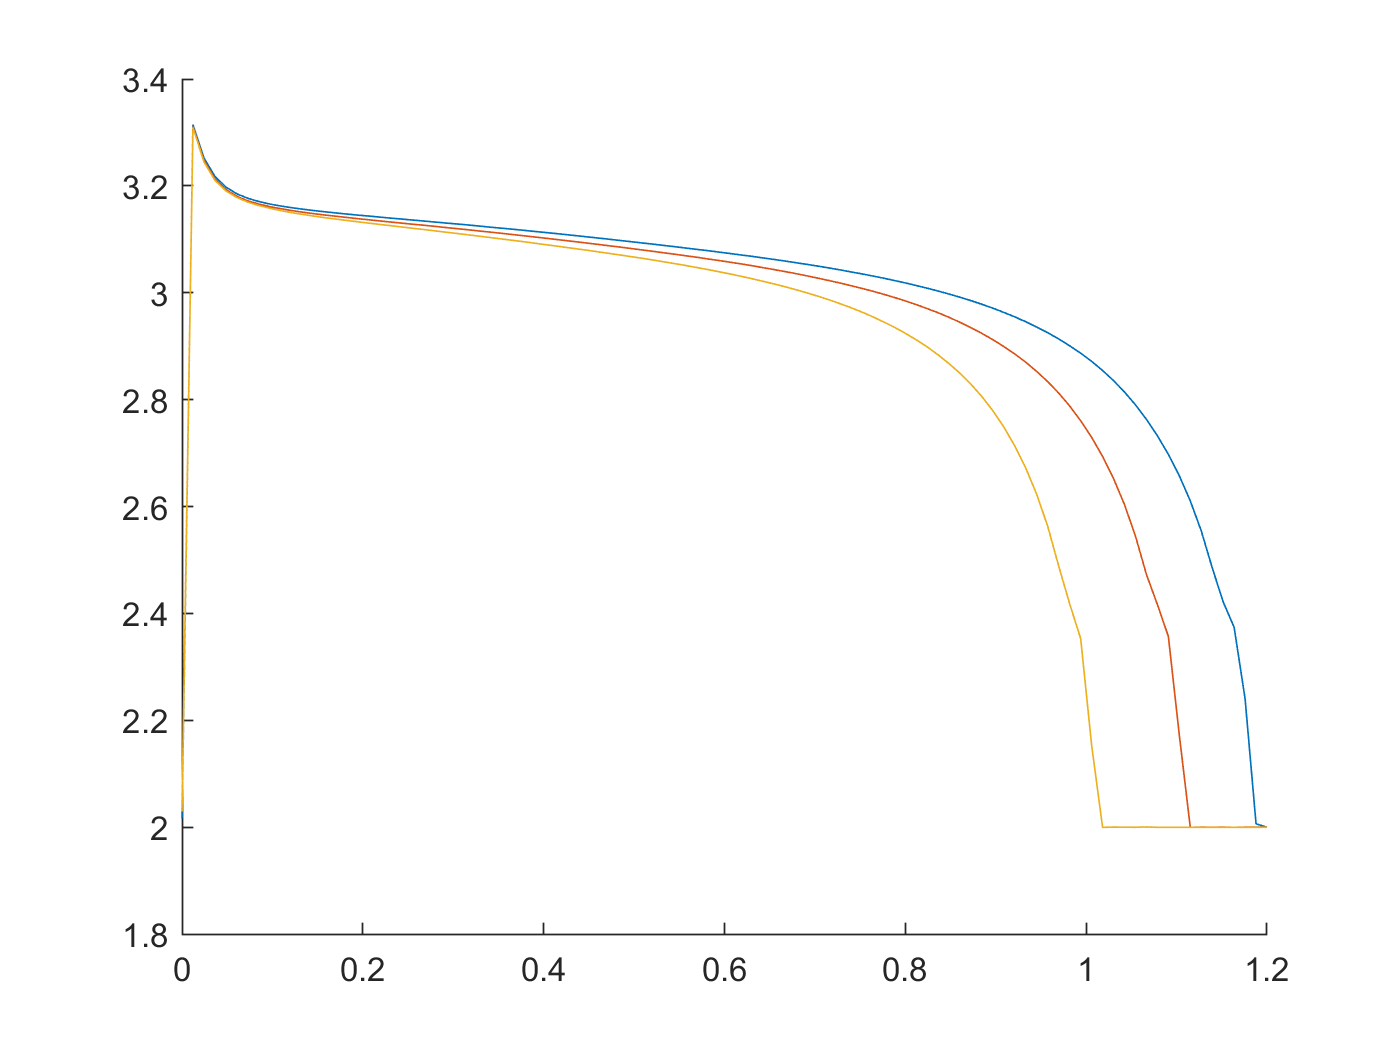


figure
hold on
for i=1:battery_dataset_new(6).cycle_life
    if rem(i,100) == 0
    plot(cap_range12,battery_dataset_new(6).Vd(i,:))
    end
end
hold off

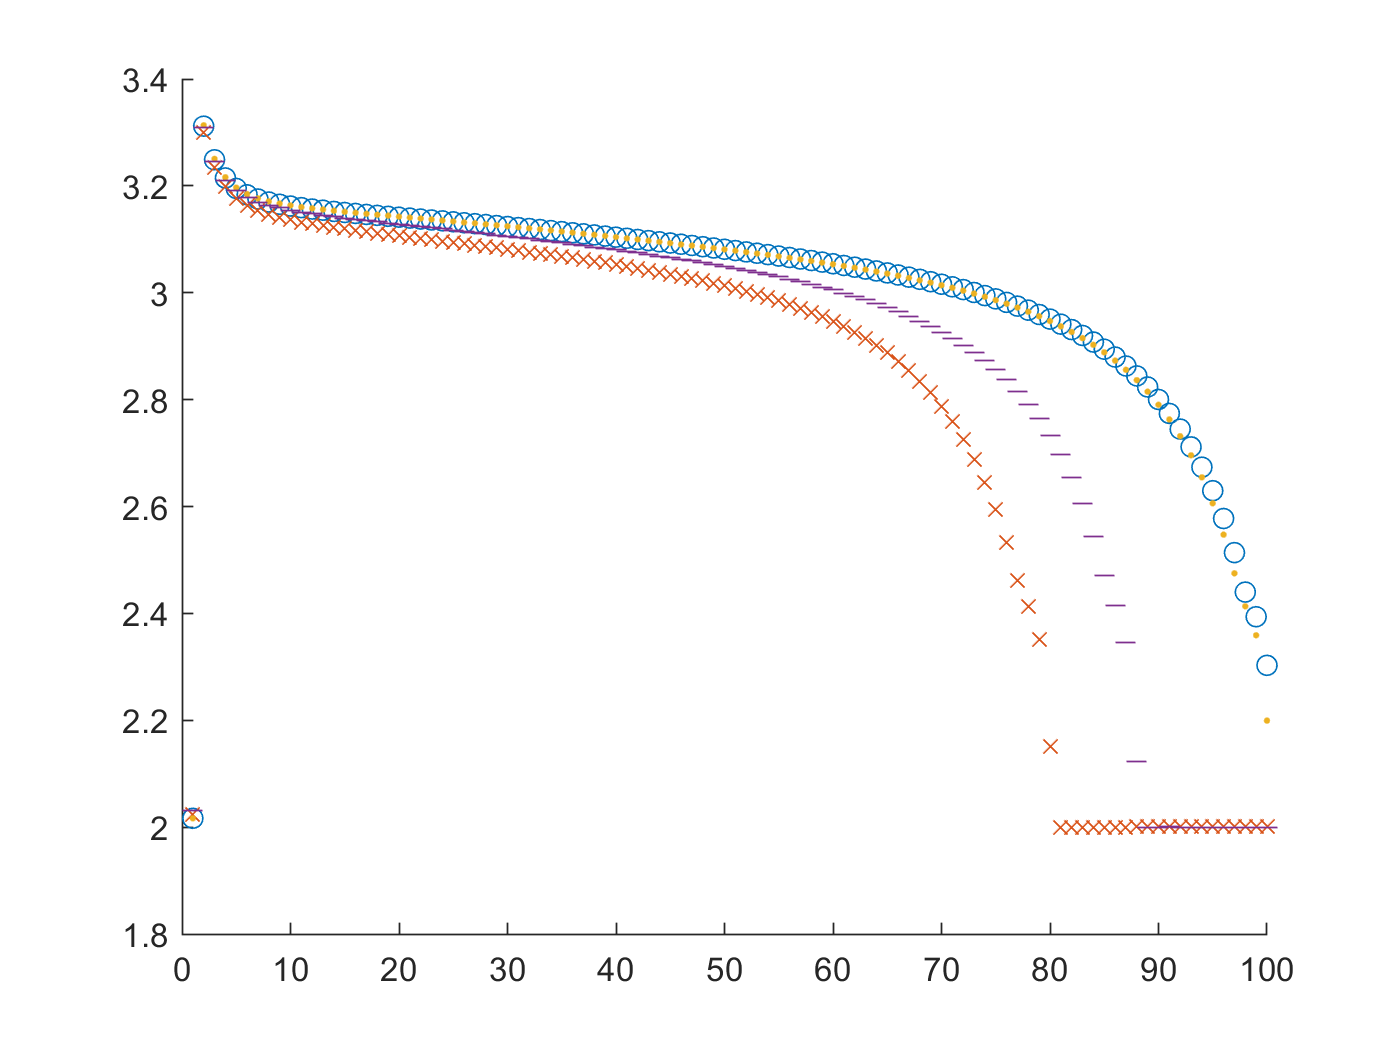

figure
hold on
    plot([1:100],battery_dataset_new(1).Vd(1,:),'o')
    plot([1:100],battery_dataset_new(1).Vd(battery_dataset_new(1).cycle_life,:),'x')
    plot([1:100],battery_dataset_new(6).Vd(1,:),'.')
    plot([1:100],battery_dataset_new(6).Vd(battery_dataset_new(3).cycle_life,:),'_')

hold off

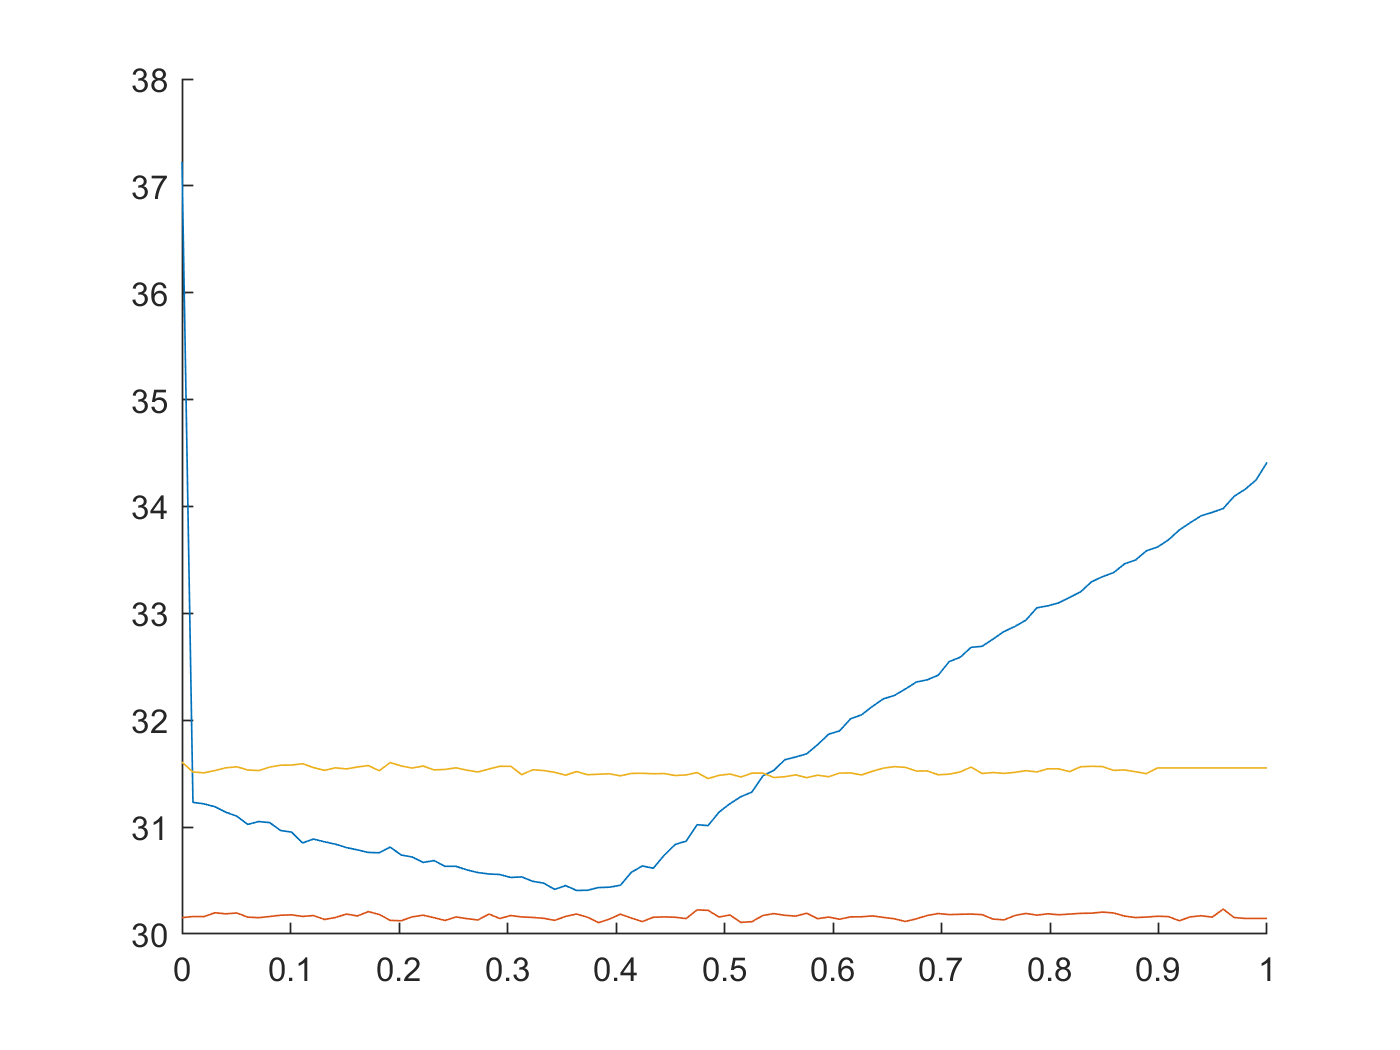




figure
hold on
for i=1:battery_dataset_new(6).cycle_life
    if rem(i,100) == 0
    plot(cap_range,battery_dataset_new(6).Td(i,:))
    end
end
hold off

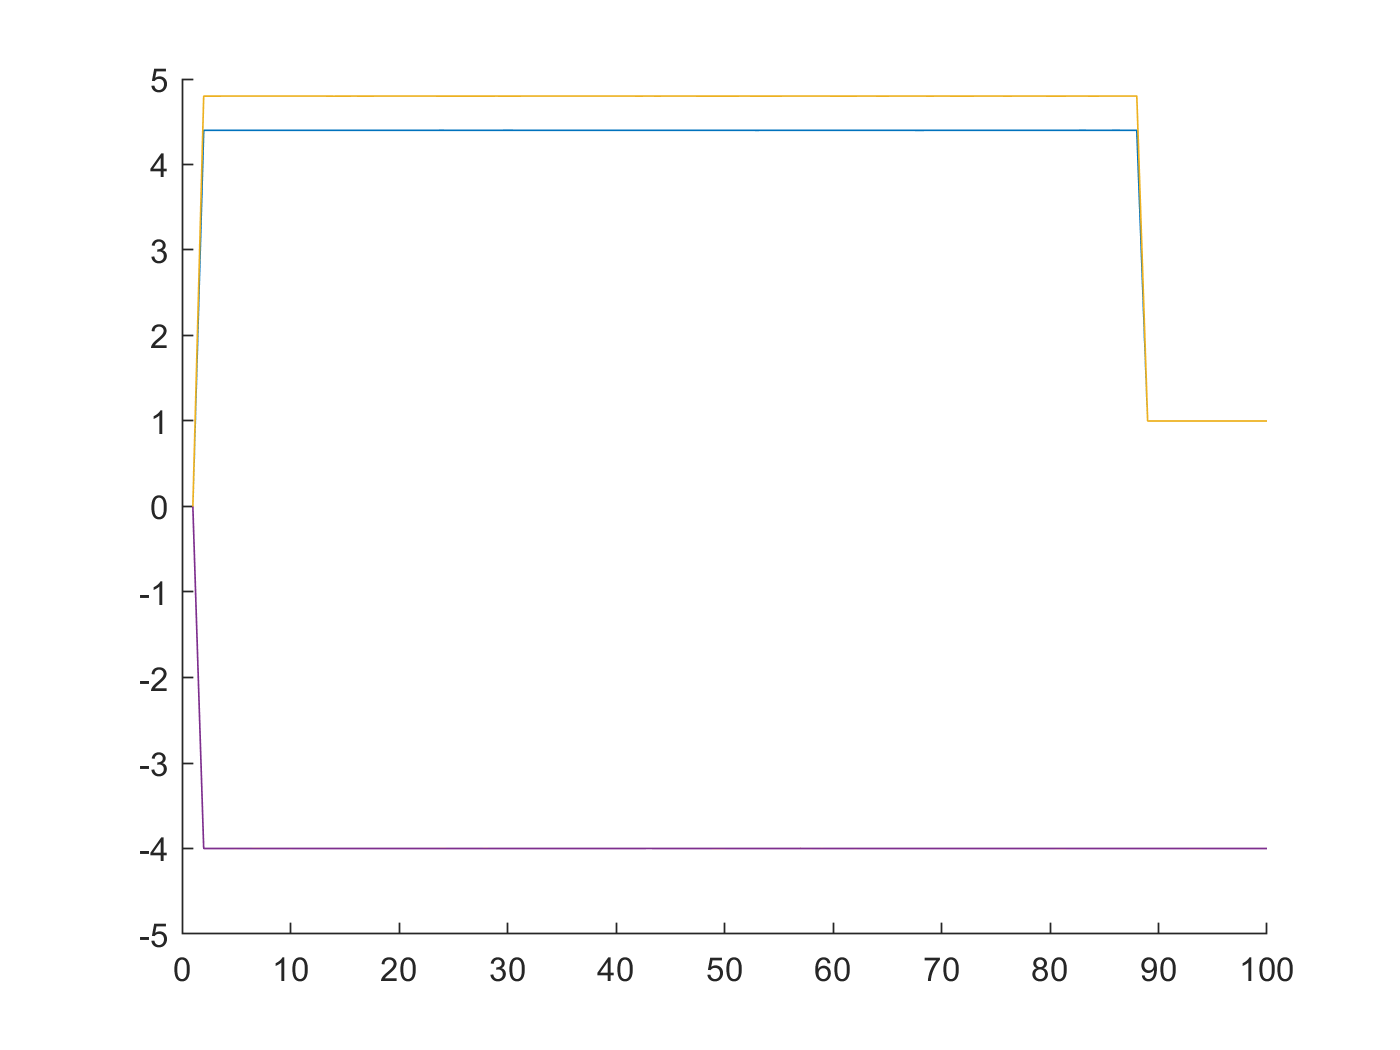


figure
hold on
plot([1:100],battery_dataset_new(1).Ic(1,:))
plot([1:100],battery_dataset_new(1).Id(1,:))
plot([1:100],battery_dataset_new(2).Ic(1,:))
plot([1:100],battery_dataset_new(2).Id(1,:))
hold off